# **Gol'dberg representation and experiment results**

**2023-04-22**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

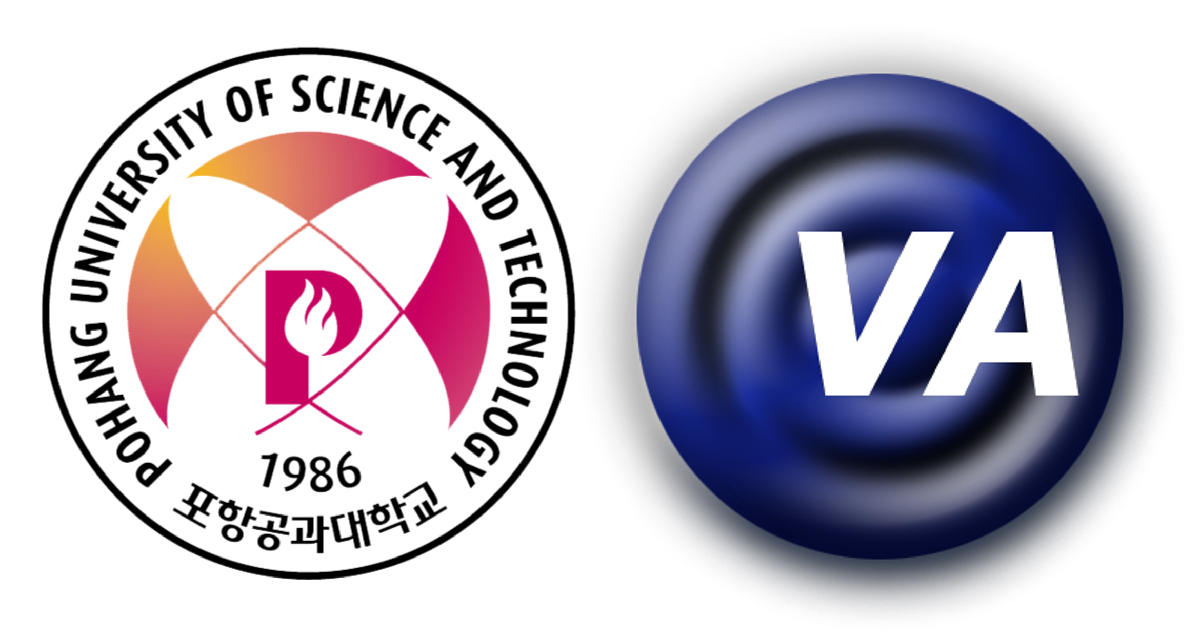

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

## 3 basic distances which control the behavior of the parametric array

- Absorption length:                 $R_{A}=L_{a}=\frac{1}{\alpha\left(f_{p}\right)}$

- Rayleigh distnace:                 $R_{F}=z_{0}
=\frac{1}{2}ka^{2}
=\frac{\pi a^{2}}{\lambda_{p}}
=\frac{\pi a^{2}f_p}{c_{0}}$

- Shock formation distance:    $R_{S}=\bar{x}
=\frac{1}{\beta \varepsilon k_{p}}
=\frac{c_0}{2\pi \beta \varepsilon f_p}
=\frac{c_0^{2}}{2\pi \beta u_p f_p}$

## Gol'dberg representation

- Gol'dberg number:                                                    $X=\Gamma=\frac{R_A}{R_S}=\frac{\beta \varepsilon k_{p}}{\alpha_p}
=\frac{2\pi \beta u_p f_p}{c_0^{2} \alpha \left(f_p \right)}$

- A properly normalized inverse Rayleigh distance:    $Y=\frac{R_A}{R_F}=\frac{\lambda_p}{\alpha_p \pi a^2}

=\frac{c_{0}}{\pi a^{2}f_p \alpha \left( f_p \right)}$

clear
air = importfile_air('air.txt');

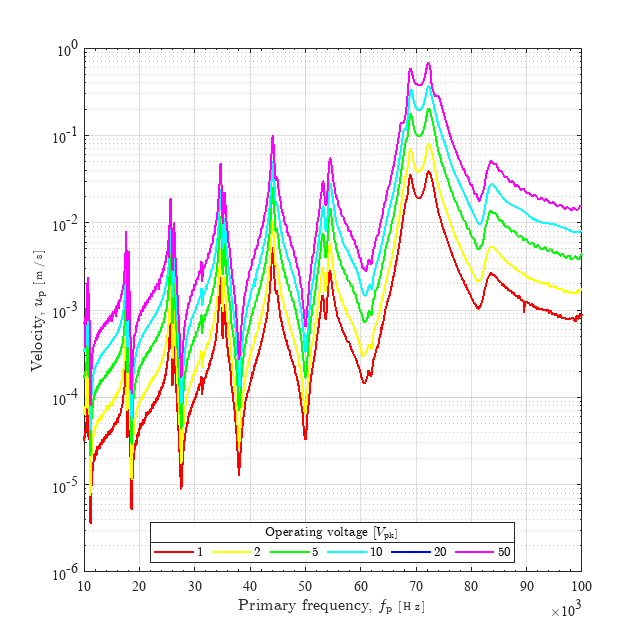

% from kcy - freq vs. measured vel (234021)
kcy_m_230421.a0 = 51.8e-3;
kcy_m_230421.fr_kcy_m_230421 = importfile_fr('kcy - freq vs. measured vel (234021).txt',6);
kcy_m_230421.fr_kcy_m_230421 = table2array(kcy_m_230421.fr_kcy_m_230421);

kcy_m_230421.freq_p = kcy_m_230421.fr_kcy_m_230421(:,1);
kcy_m_230421.u_pt   = medfilt1(kcy_m_230421.fr_kcy_m_230421(:,2:7),3,[],2);
% kcy_m_230421.u_pt   = kcy_m_230421.fr_kcy_m_230421(:,2:7);

% find the index of maxima
kcy_m_230421.u_pt_peak = kcy_m_230421.u_pt(islocalmax(kcy_m_230421.u_pt(:,1),'MaxNumExtrema',2));
kcy_m_230421.peak_idx(1) = find(kcy_m_230421.u_pt(:,1)==kcy_m_230421.u_pt_peak(1));
kcy_m_230421.peak_idx(2) = find(kcy_m_230421.u_pt(:,1)==kcy_m_230421.u_pt_peak(2));

createfigure_xy_multi(kcy_m_230421.freq_p', kcy_m_230421.u_pt', ...
        'Primary frequency, $f_\mathrm{p}$ [Hz]','Velocity, $u_\mathrm{p}$ [m/s]', ...
    'linear','log','centimeters',12,12,'Operating voltage $\left[ V_{\mathrm{pk}} \right]$',["1" "2" "5" "10" "20" "50"],6)

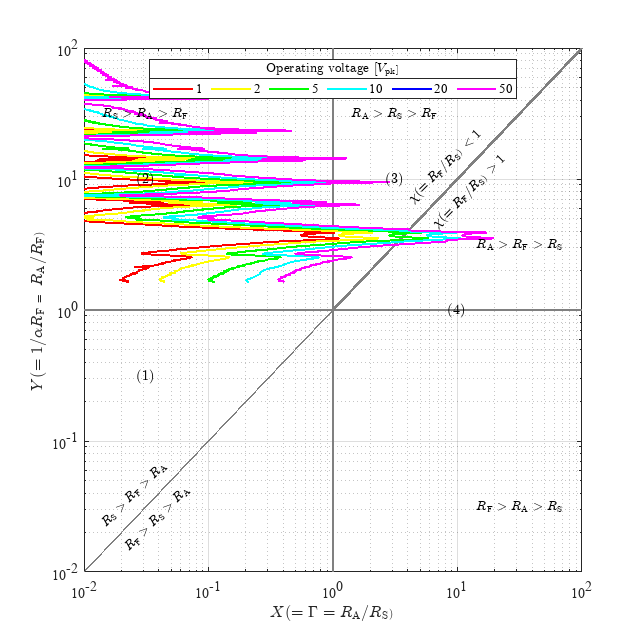


% Absorption length
kcy_m_230421.alpha = air_absorption(kcy_m_230421.freq_p,20,20,1)/8.686;
kcy_m_230421.l_alpha = 1./kcy_m_230421.alpha;
% Rayleigh distance
kcy_m_230421.z0 = pi*kcy_m_230421.a0.^2*kcy_m_230421.freq_p/air.c0;
% Shock formation distance
kcy_m_230421.z_t = air.c0^2./(2*pi*air.beta*kcy_m_230421.u_pt.*kcy_m_230421.freq_p);

kcy_m_230421.X = repmat(kcy_m_230421.l_alpha./kcy_m_230421.z_t, 1);
kcy_m_230421.Y = repmat(kcy_m_230421.l_alpha./kcy_m_230421.z0, [1 6]);
createfigure_goldberg(kcy_m_230421.X, kcy_m_230421.Y, 'log','Operating voltage $\left[ V_{\mathrm{pk}} \right]$',["1" "2" "5" "10" "20" "50"],2);

% % Absorption length
% kcy_m_230421.l_alpha(kcy_m_230421.peak_idx)
% % Rayleigh distance
% kcy_m_230421.z0(kcy_m_230421.peak_idx)
% % Shock formation distance
% kcy_m_230421.z_t(kcy_m_230421.peak_idx,:)
% kcy_m_230421.X(kcy_m_230421.peak_idx,:)
% kcy_m_230421.Y(kcy_m_230421.peak_idx,:)
kcy_m_230421.bl_peak = ...
    table(kcy_m_230421.freq_p(kcy_m_230421.peak_idx),...
    kcy_m_230421.l_alpha(kcy_m_230421.peak_idx),...
    kcy_m_230421.z0(kcy_m_230421.peak_idx),...
    kcy_m_230421.z_t(kcy_m_230421.peak_idx,:),...
    'VariableNames',["freq_peak" "l_a" "z_0" "z_"]);
kcy_m_230421.bl_peak = splitvars(kcy_m_230421.bl_peak, ...
    'z_','NewVariableNames',{'z_01' 'z_02' 'z_05' 'z_10' 'z_20' 'z_50'});
disp(kcy_m_230421.bl_peak)

    freq_peak     l_a       z_0       z_01      z_02      z_05      z_10      z_20       z_50  
    _________    ______    ______    ______    ______    ______    ______    _______    _______

      68978      6.6155    1.6952    6.4315    3.1697    1.2895    0.6891    0.38662    0.38662
      72317      6.2511    1.7773     5.578    2.6992     1.066    0.5903    0.32542    0.32542



kcy_m_230421.gol_peak = ...
    table(kcy_m_230421.freq_p(kcy_m_230421.peak_idx),...
    kcy_m_230421.X(kcy_m_230421.peak_idx,:),...
    kcy_m_230421.Y(kcy_m_230421.peak_idx)',...
    'VariableNames',["freq_peak" "X" "Y"]);
kcy_m_230421.gol_peak = splitvars(kcy_m_230421.gol_peak, ...
    'X','NewVariableNames',{'X_01' 'X_02' 'X_05' 'X_10' 'X_20' 'X_50'});
disp(kcy_m_230421.gol_peak)

    freq_peak     X_01      X_02      X_05      X_10      X_20      X_50       Y   
    _________    ______    ______    ______    ______    ______    ______    ______

      68978      1.0286    2.0871    5.1301    9.6001    17.111    17.111    3.9024
      72317      1.1207    2.3159    5.8639     10.59    19.209    19.209    3.5173



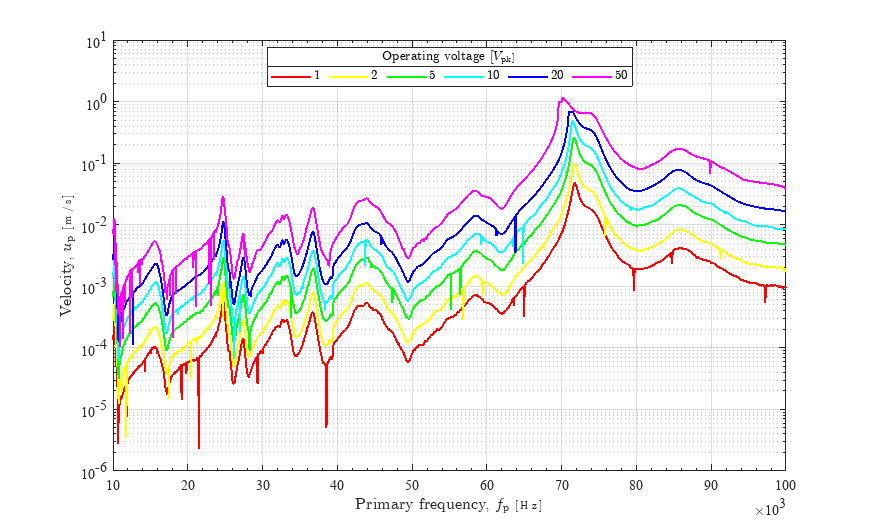

% from obs - freq vs. measured vel (234021)
obs_m_230421.a0 = 50e-3;
obs_m_230421.fr_obs_m_230421 = importfile_fr('obs - freq vs. measured vel (234021).txt',6);
obs_m_230421.fr_obs_m_230421 = table2array(obs_m_230421.fr_obs_m_230421);

obs_m_230421.freq_p = obs_m_230421.fr_obs_m_230421(:,1);
obs_m_230421.u_pt   = obs_m_230421.fr_obs_m_230421(:,2:7);

createfigure_xy_multi(obs_m_230421.freq_p', obs_m_230421.u_pt', ...
        'Primary frequency, $f_\mathrm{p}$ [Hz]','Velocity, $u_\mathrm{p}$ [m/s]', ...
    'linear','log','centimeters',18,9,'Operating voltage $\left[ V_{\mathrm{pk}} \right]$',["1" "2" "5" "10" "20" "50"],6)

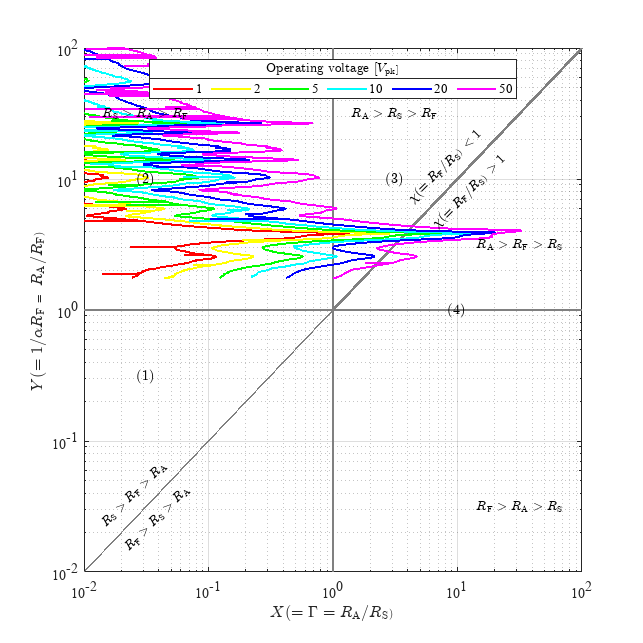


% find the index of maxima
obs_m_230421.u_pt_peak = obs_m_230421.u_pt(islocalmax(obs_m_230421.u_pt(:,1),'MaxNumExtrema',2));
obs_m_230421.peak_idx(1) = find(obs_m_230421.u_pt(:,1)==obs_m_230421.u_pt_peak(1));
obs_m_230421.peak_idx(2) = find(obs_m_230421.u_pt(:,1)==obs_m_230421.u_pt_peak(2));

% Absorption length
obs_m_230421.alpha = air_absorption(obs_m_230421.freq_p,20,20,1)/8.686;
obs_m_230421.l_alpha = 1./obs_m_230421.alpha;
% Rayleigh distance
obs_m_230421.z0 = pi*obs_m_230421.a0.^2*obs_m_230421.freq_p/air.c0;
% Shock formation distance
obs_m_230421.z_t = air.c0^2./(2*pi*air.beta*obs_m_230421.u_pt.*obs_m_230421.freq_p);

obs_m_230421.X = repmat(obs_m_230421.l_alpha./obs_m_230421.z_t, 1);
obs_m_230421.Y = repmat(obs_m_230421.l_alpha./obs_m_230421.z0, [1 6]);
createfigure_goldberg(obs_m_230421.X, obs_m_230421.Y, 'log','Operating voltage $\left[ V_{\mathrm{pk}} \right]$',["1" "2" "5" "10" "20" "50"],2);

% % Absorption length
% obs_m_230421.l_alpha(obs_m_230421.peak_idx)
% % Rayleigh distance
% obs_m_230421.z0(obs_m_230421.peak_idx)
% % Shock formation distance
% obs_m_230421.z_t(obs_m_230421.peak_idx,:)
% obs_m_230421.X(obs_m_230421.peak_idx,:)
% obs_m_230421.Y(obs_m_230421.peak_idx,:)
obs_m_230421.bl_peak = ...
    table(obs_m_230421.freq_p(obs_m_230421.peak_idx),...
    obs_m_230421.l_alpha(obs_m_230421.peak_idx),...
    obs_m_230421.z0(obs_m_230421.peak_idx),...
    obs_m_230421.z_t(obs_m_230421.peak_idx,:),...
    'VariableNames',["freq_peak" "l_a" "z_0" "z_"]);
obs_m_230421.bl_peak = splitvars(obs_m_230421.bl_peak, ...
    'z_','NewVariableNames',{'z_01' 'z_02' 'z_05' 'z_10' 'z_20' 'z_50'});
disp(obs_m_230421.bl_peak)

    freq_peak     l_a       z_0       z_01      z_02      z_05       z_10       z_20       z_50  
    _________    ______    ______    ______    ______    _______    _______    _______    _______

      71749      6.3113    1.6429    4.5984    2.1928    0.86037    0.52607    0.36941    0.30349
      86002      4.9943    1.9693    43.371    21.791      8.795     4.7512     2.3682     1.0684



obs_m_230421.gol_peak = ...
    table(obs_m_230421.freq_p(obs_m_230421.peak_idx),...
    obs_m_230421.X(obs_m_230421.peak_idx,:),...
    obs_m_230421.Y(obs_m_230421.peak_idx)',...
    'VariableNames',["freq_peak" "X" "Y"]);
obs_m_230421.gol_peak = splitvars(obs_m_230421.gol_peak, ...
    'X','NewVariableNames',{'X_01' 'X_02' 'X_05' 'X_10' 'X_20' 'X_50'});
disp(obs_m_230421.gol_peak)

    freq_peak     X_01       X_02      X_05       X_10      X_20      X_50       Y   
    _________    _______    ______    _______    ______    ______    ______    ______

      71749       1.3725    2.8782     7.3356    11.997    17.085    20.796    3.8415
      86002      0.11515    0.2292    0.56786    1.0512    2.1089    4.6747    2.5362

